# Exploring Image Compression

**Note 1**: Following along with this live script will write image files to your computer.

**Note 2**: File sizes vary slightly from computer to computer, so the file size you see may be different than what is mentioned here.

In the previous video, you saw how to save images and how the file size can vary depending on the settings used when writing the files. A detailed investigation of compression algorithms is beyond the scope of this course (and is unnecessary for most applications). However, understanding the impacts on file size when saving images is important. In this reading, you'll look at two images and two common file types to investigate file compression. If you work with large image datasets, thinking about file size is important.

## Factors Impacting File Size

Several factors impact file size:

- image resolution: more pixels mean more numbers to store. But higher resolution doesn't always mean higher file size as you will soon see

- image content: images with lots of variations in color and intensity cannot be compressed as much as images with little variation

- compression algorithm:  lossless compression will require more memory than lossy compression

- compression settings:  for JPG, you can specify the "Quality" factor. Higher quality factors will reproduce the images more closely

## Load Images for Investigation

In this reading you will look at two images included with the course files:

- image of the Orion Nebula (the non-averaged "OrionNebula1.png"): **29.3 MB PNG on hard drive**

- image of the moon ("half moon.jpg"): **2.2 MB JPG on hard drive**

Both images were taken with the same camera but saved with different compression algorithms, which is why the file types are different. The Orion Nebula image was save using lossless compression from the raw data. It has a smaller image size because it was cropped to align it with the other Orion images. The moon image was saved as a JPG using the default camera settings of high quality. *The raw image data cannot be recovered from a JPG*.

**Run this section to load the images and compare the file size**

orion = imread("OrionNebula1.png");
moon = imread("half moon.JPG");

Display the memory required to store the data in MATLAB. How does the ratio of memory in MATLAB compare to the memory on disk? (Note that the whos command shows the memory Bytes. 1 MB = 10^6 Bytes)

whos orion moon

  Name          Size                   Bytes  Class    Attributes

  moon       3456x5184x3            53747712  uint8              
  orion      3215x5121x3            49392045  uint8              



The moon image is slightly larger when loaded into MATLAB but requires less than 1/10th the memory on disk! Both are `uint8` color images, so every number requires 1 byte of memory to store. Clearly the moon image is much more compressed than the Orion image. Let's explore why this is.

## Comparing File Types

The Orion image is a PNG file while the moon image is a JPG. Remember that PNG files use lossless compression while JPG files use lossy compression. To test if the compression algorithm is the most important factor for these two images, save them as the other file type and compare the new size.

If the moon image memory on disk increases to near 29 MB and the Orion image memory on disk decreases to near 3 MB, then the compression algorithm accounts for most of the difference in file size.

**Run this section to save new image files and compare the file size**

imwrite(orion, "Orion JPG version.jpg", "Quality", 100);
imwrite(moon, "half moon PNG version.png");

Use the meta-data to compare file size (or use your file explorer). The file size on disk is contained in the `FileSize` field of the structure returned by the `imfinfo` function.

orionJPGinfo = imfinfo("Orion JPG version.jpg");
orionJPGmemory = orionJPGinfo.FileSize
moonPNGinfo = imfinfo("half moon PNG version.png");
moonPNGmemory = moonPNGinfo.FileSize

Compare the moon PNG version to the Orion JPG version. 

moonPNGmemory/orionJPGmemory

The file size of the Orion JPG image is reduced to about 15.4 MB. The moon PNG file size only increased to about 3.8 MB. Clearly, file type does not explain the difference in file size.

## Explore the Image Content

Open both images in the Image Viewer App or a figure window and explore the pixel values. Zoom into different regions of each image and pay attention to how pixel values change. Which image seems to have more variation? Zoom into regions that appear black in each image. How do they compare? 

Look back to the beginning of this reading for a list of factors that affect file size. Which factor do you think has the largest impact for the images you investigated here? Post your thoughts on the discussion forums.

imtool("half moon PNG version.png")
imtool("Orion JPG version.jpg")


## Examine the Differences Between File Types

### PNG Files

Recall that the moon image was already a JPG, so the original data cannot be recovered. However, above you saved the data as a PNG file. PNG files use lossless compression, meaning the saved image data exactly reproduces the original image. To verify this, load and compare the PNG version of the half moon image you just created to the JPG version loaded at the beginning of this reading.

**Run this section load the PNG moon image and compare it to the JPG**

moonPNG = imread("half moon PNG version.png");

The `isequal` function compares to variables and returns true (logical 1) if the variables are equal. 

Compare `moonPNG` to `moon` created earlier.

isequal(moonPNG, moon)

Saving as a PNG exactly reproduced the JPG image you loaded at the beginning of this script.

### JPG Files

JPG files use lossy compression. Even using the highest quality settings will result in some data loss. To see this, save the moon image as a new JPG file. Then load the new JPG image and compare to the original JPG loaded at the beginning of this script.

**Run this section to create a new moon JPG image and compare to the original**

imwrite(moon, "new half moon JPG.jpg", "Quality", 100);
moonJPG2 = imread("new half moon JPG.jpg");
isequal(moon, moonJPG2)

ans = logical
   0


The two images are not equal! 

## Visually Compare Two Images

It's common to compare two images and look for subtle changes. In this case, you want to compare differences between the "half moon.JPG" image and the "new half moon JPG.jpg" images. 

Recall, that before doing arithmetic on images, you need to convert them to double. 

**Run this section to subtract the new JPG moon image from the starting image and see the result**

newMoonJPG = imread("new half moon JPG.jpg");
moonDiff = im2double(moon) - im2double(newMoonJPG);

Visualize the result

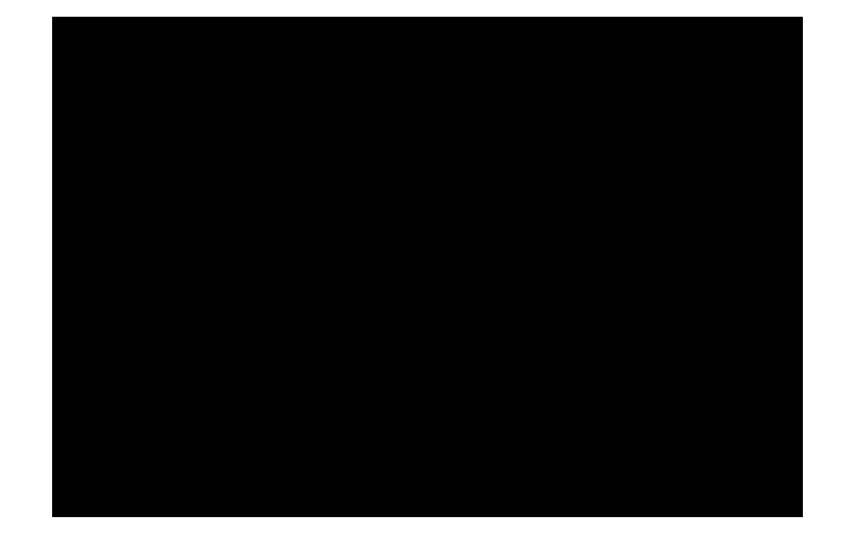

imshow(moonDiff)

## Visually Compare Two Images: Part 2

The result above looks all black. The main reason for this is:

- The differences are small and `imshow` assumes double images have the range [0 1]. The variable `moonDiff` has negative numbers. 

Using the `imshow` function on images that have data out of range results in misleading images. All negative values in `moonDiff` will display as 0. Because you're looking at the difference between two images, pixels with a negative value will appear to have 0 difference, which is not correct!  

Recall that you can use a 2nd input to the `imshow` function to automatically scale the range, but this only works for grayscale images, not color. Therefore, you must use individual color planes to visualize the differences between the two color images. 

- extract a color plane of the difference image

- use empty brackets as a second input to the `imshow` function to auto scale the range

**Run this section to view the difference of the green color plane**

Add a colorbar to see the scale of the differences.

imshow(moonDiff(:,:,2), [])
colorbar

## Further Exploration

Notice how small the differences are between the two images. Try decreasing the quality factor when saving the new JPG image and compare the size of the differences to what you saw above. 

How about the JPG Orion image? What differences do you see there? Try decreasing the quality and compare the JPG version to the PNG. Is there a pattern to the differences? 

*Remember that *`imshow`* expects a range of [0 1] for images of type double and color images***.** You need to use empty brackets and look at a single color plane when visualizing differences between images.

*Copyright 2022 The MathWorks, Inc.*